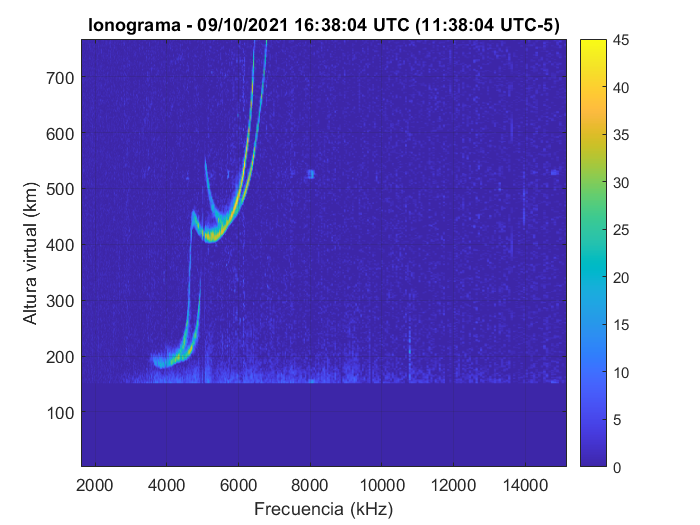

cd(Folders.FolderCodesFunc)
% Get data
IonogramData = GettingRelevantData(zippedDataFrame, Folders);

totalpowerData = IonogramData.totalpowerData;
NoisetotalpowerData = IonogramData.NoisetotalpowerData;
RangeData = IonogramData.RangeData;
% Denoising 1
imgDen_1 = Denoising_1(totalpowerData, NoisetotalpowerData, RangeData);
CustomPlot(IonogramData, imgDen_1)

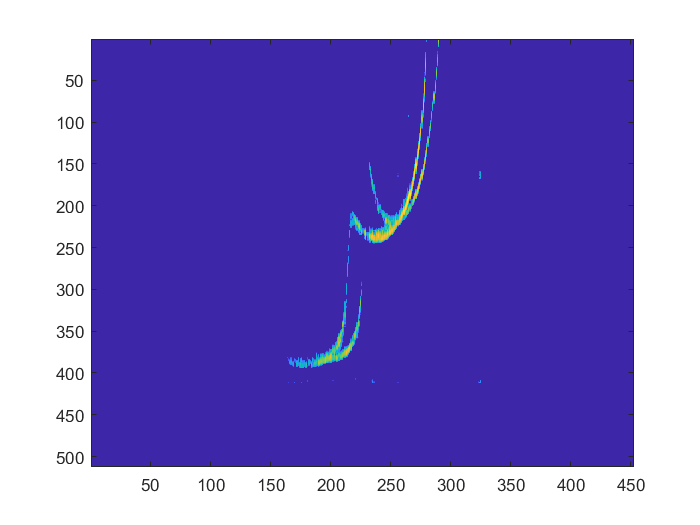


% % Thresholding global 1
% imgThresh = uint8(ThreshImg_Global(b));
% CustomPlot(IonogramData, imgThresh);
% iIonCCL = bwlabel(imgThresh);
% figure, imagesc(flip(iIonCCL))

% Laplacian Filter
sharpened = LaplacianFilter(imgDen_1);

    
%%%%%%%%%%%%
%     %// Change - Normalize the sharpened result
%     varSharp_ = imsubtract(sharpened,double(~sharpened));
%     minA = min(varSharp_(:));
%     maxA = max(varSharp_(:));
%     varSharp_ = (varSharp_ - minA) / (maxA - minA);
%     
%     %// Change - Perform linear contrast enhancement
%     varSharp_ = imadjust(varSharp_, [60/255 200/255], [0 1]);
%     %%%%%%%%%%%%

% Eliminate outliners pixels
[Projx_Den, Projy_Den] = Projection(imgDen_1);
[Projx_Sharp, Projy_Sharp] = Projection(sharpened);

a = AreaFiltering(sharpened, Projy, 'y');
b = AreaFiltering(a,Projx, 'x');
imagesc(flip(b))


%     minA = 0;
%     maxA = 1;
%     varSharp_ = (Projy_Sharp - minA) / (maxA - minA);
    varDen_ =normalize(Projy_Den,'range');
    figure, plot(varDen_)
    title("denNorm")
    var_ = varDen_+Projy_Sharp;
    figure, plot(var_)
    title("Sum")
    figure, plot(Projy_Sharp)
    title("Projy_Sharp")
    figure, plot(Projy_Den)
    title("Projy_Den")
    
    img = imgDen_1;
    ncolumnsXnrows = size(img);
    % proyx=zeros(ncolumnsXnrows(2), 1); % Para x
    proyx_nFila = linspace(1,ncolumnsXnrows(2),ncolumnsXnrows(2));
    
    % proyy=zeros(ncolumnsXnrows(1), 1); % Para Y
    proyy_nFila = linspace(1,ncolumnsXnrows(1),ncolumnsXnrows(1));
    
        % [xData, yData] = prepareCurveData( proyx_nFila, Projx );

        % Set up fittype and options.
        ft = fittype( 'gauss1' );
        % opts = fitoptions( 'Method', 'NonlinearLeastSquares' );
        % opts.Display = 'Off';
        % opts.Lower = [-Inf -Inf 0];
        % opts.StartPoint = [2030.953540802 281 42.1041558348371];
        
        % Fit model to data.
        [fitresult, gof] = fit( proyx_nFila', Projx, ft);
        a = max(Projx)
        val =  a*exp(-((xData-fitresult.b1)./fitresult.c1).^2);
        % max(findpeaks(Projx))
        
    zz = (x>=5).*exp(-2*x);
    plot(zz)
    
    [pks,locs,w,p] = findpeaks(Projy_Den); % ,'MinPeakProminence', 10,'Annotate','extents')
    z_ = sort(p,'descend')
    figure, findpeaks(Projy_Sharp,'MinPeakProminence', z_(2),'Annotate','extents')
    
%         x = proyy_nFila;
%     y = Projy;
%     ft = fittype( 'a + b*mod((x - c)/d,1)', 'independent', 'x', 'dependent', 'y' );
%     
%     strideguess = (max(x) - min(x))/5;
%     breakguess = 25;
%     abcdstart = [min(y),(max(y) - min(y))/strideguess,breakguess,strideguess];
%     opts.StartPoint = [abcdstart abcdstart abcdstart abcdstart];
%     mdl = fit([x,y], ft, opts)
    
    
%     mdl = 
%          General model:
%          mdl(x) = A + B*mod((x - C)/D,1)
%          Coefficients (with 95% confidence bounds):
%            A =       2.613  (-1.168e+07, 1.168e+07)
%            B =       3.536  (2.861, 4.21)
%            C =       25.37  (-6.265e+07, 6.265e+07)
%            D =       18.96  (18.14, 19.79)
    plot(mdl)
    hold on
    plot(x,y,'o')
    
        
        
a = AreaFiltering(sharpened, Projy, 'y');
b = AreaFiltering(a,Projx, 'x');
% CustomPlot(IonogramData, b)
iIonCCL = bwlabel(b);
figure, imagesc(flip(iIonCCL))
title("Area filter")

% % gaussian filter
%     imgVar_ = b;
%     imgVar_ = imgVar_(imgVar_~=0);
%     
%     B = imgaussfilt(b, std(double(imgVar_)), 'FilterSize', 101, 'FilterDomain', 'spatial');
%     % CustomPlot(IonogramData, B);
%     iIonCCL = bwlabel(B);
%     figure, imagesc(flip(iIonCCL))

% Thresholding global 2
    imgThresh = uint8(ThreshImg_Global2(b));
    % CustomPlot(IonogramData, imgThresh);
    iIonCCL = bwlabel(imgThresh);
    figure, imagesc(flip(iIonCCL))
    title("Thresholding global 2")
    

F = fft2(iIonCCL);
figure; imagesc(fftshift(log10(abs(F))+1));

% imshowpair(flip(IonogramData.totalpowerData), flip(sharpened))
imshowpair(flip(IonogramData.totalpowerData), flip(sharpened),'montage')

% imgVar_ = iIonCCL;
% imgVar_ = imgVar_(imgVar_~=0);
% I = iIonCCL;
% I_filtered = I - imfilter( I, fspecial('Gaussian', 3, std(imgVar_))); 
% %imtool( I_filtered );


% % Dilate
% SE = strel('rectangle',[3 3]); % lo cambie de 3x3 a 4x6 para que se parezca al paper
% iIonDil = imdilate(b,SE);

% iIonCCL = bwlabel(b);
% figure, imagesc(flip(iIonCCL))

% % Median filter salt & pepper
% outpict = medfilt2(iIonCCL, [10, 10]);
% %outpict = imadjust(outpict,[0.15 0.85]);
% figure, imagesc(flip(outpict))

cd(Folders.FolderCodes)
